clear

%パラメータ
L = 0.045; %端子間インダクタンス[mH]　
R = 2.9; %端子間抵抗[ohm]
Kt = 3.52e-3; %トルク定数[Nm/A]
J = 0.151e-7; %イナーシャ[kgm^2]
d = 0.00001; % 粘性抵抗
Ke = 1 / (2 * pi * 2710 / 60); %逆起電定数 [V/(rad/s)]

r = 0.012; %タイヤの半径 [m]
m = 0.150; %ロボットの重量[kg]
g = 1; %減速比


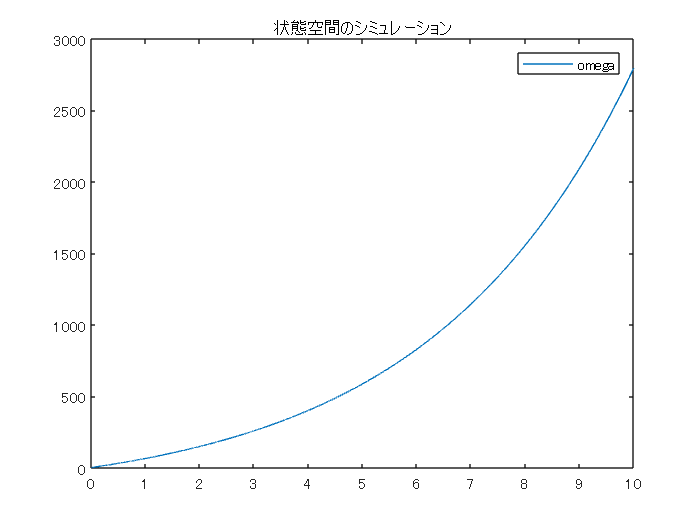

%状態空間表現
A = [d/(m*r^2 + J),Kt/(m*r^2 + J); -Ke/L, -R/L];
B = [0; 1/L];
C = [1, 0];
D = 0;
sys_state = ss(A,B,C,D);

%状態空間でシミュレーション
dt = 0.001;
t = 0 : dt : 10;
N = length(t);
i = 0;
x = [0; 0];
u = 1;
x1 = zeros(1, N);
x2 = zeros(1, N);
for n = t
    i = i + 1;
    dx = A * x + B * u;
    x = x + dx * dt;
    
    x1(i) = [x(1)];
    x2(i) = [x(2)];
end


plot(t, x1);
legend('omega')
title('状態空間のシミュレーション')

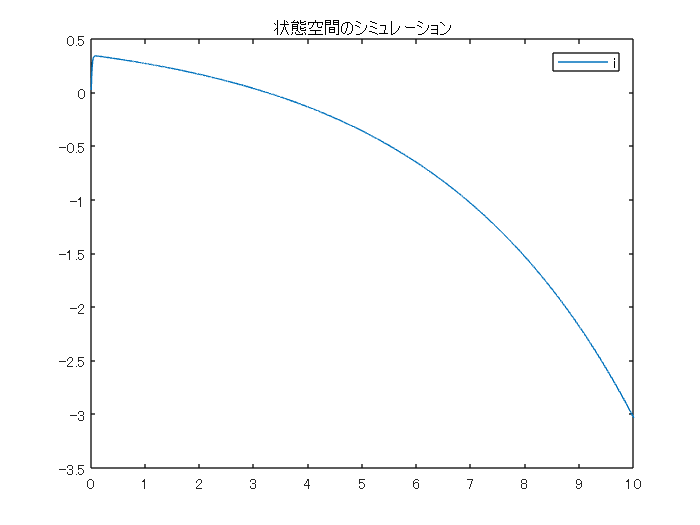


plot(t, x2);
legend('i')
title('状態空間のシミュレーション')

% 可制御　可観測
Uc = [B, A*B];
if det(Uc) ~= 0
    disp('可制御である')
end

可制御である


Uo = [C; C*A];

if det(Uo) ~= 0
    disp('可観測である')
end

可観測である


%ゲインを求める
Q = [1, 0;
      0, 1];
R = 1;
f = lqr(A, B, Q, R)

f =     1.0105    2.0214


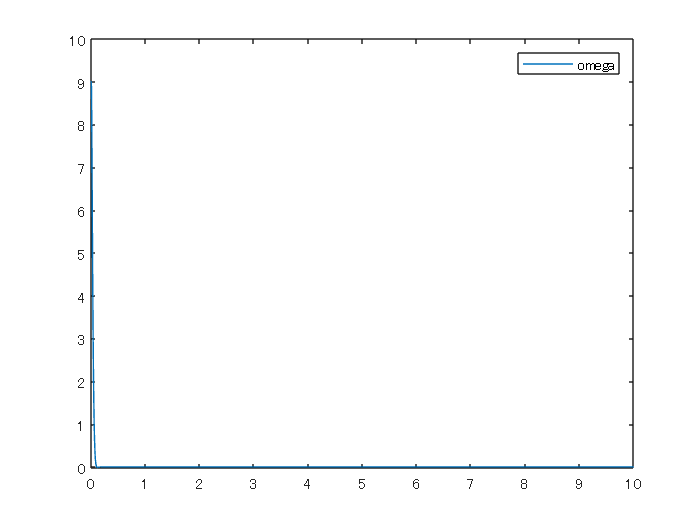

% 状態フィードバックのシミュレーション
x0 = [9; 0]; % 初期値
u = 0; % 入力の初期値
x = x0;

s_x1 = [];
s_x2 = [];
s_u = [];
for n = t
    dx = A * x + B * u;
    x = x + dx * dt;
    u = -f*x;
    
    s_x1 = [s_x1 x(1)];
    s_x2 = [s_x2 x(2)];
    s_u = [s_u u];

end

plot(t, s_x1);
legend('omega')

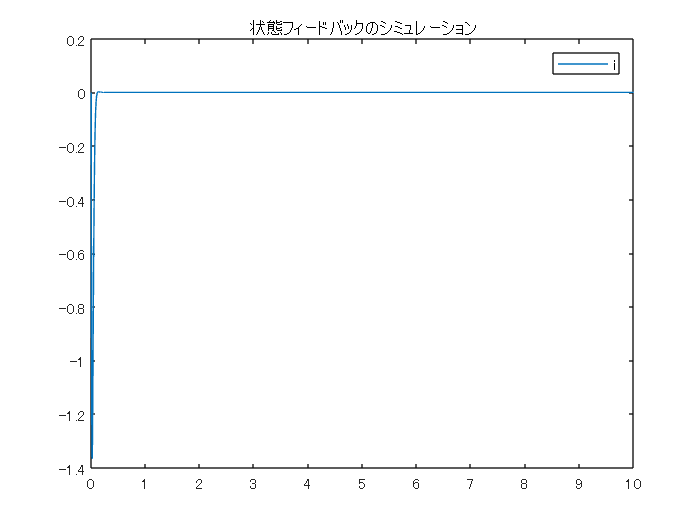

plot(t, s_x2);
legend('i')
title('状態フィードバックのシミュレーション')

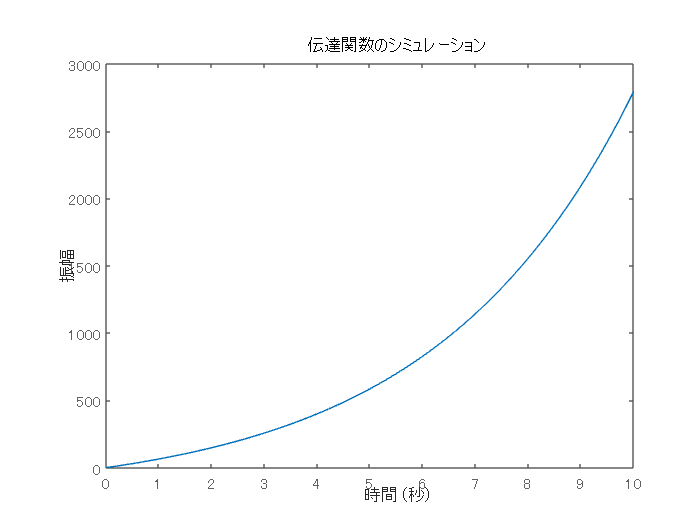


%伝達関数に変換
[b, a] = ss2tf(A, B, C, D); %b/a
sys_tf = tf(b, a);

step(sys_tf, 10)
title("伝達関数のシミュレーション")